Processing dataset: TSVD


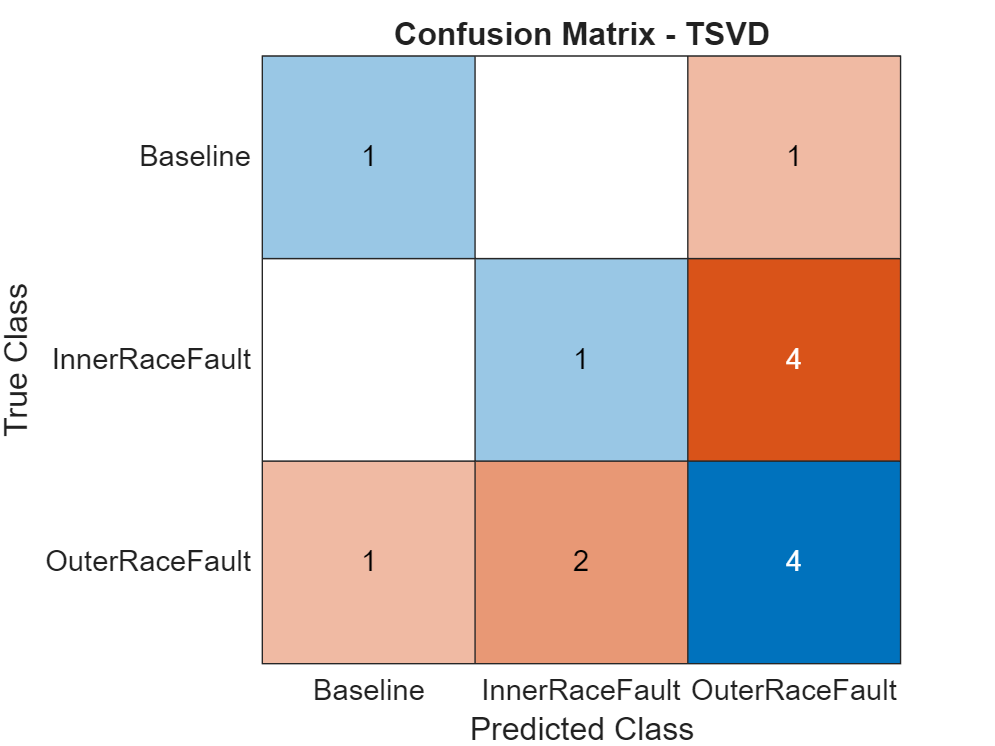


Accuracy: 0.4286


Processing dataset: RSVD


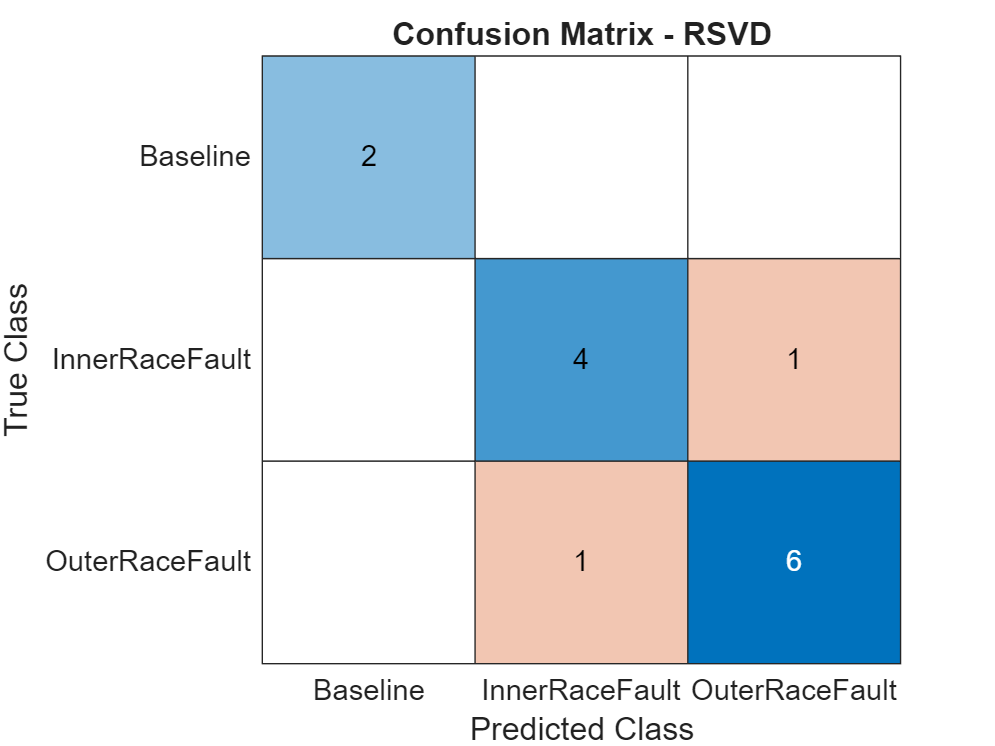


Accuracy: 0.8571


Processing dataset: WSSVD


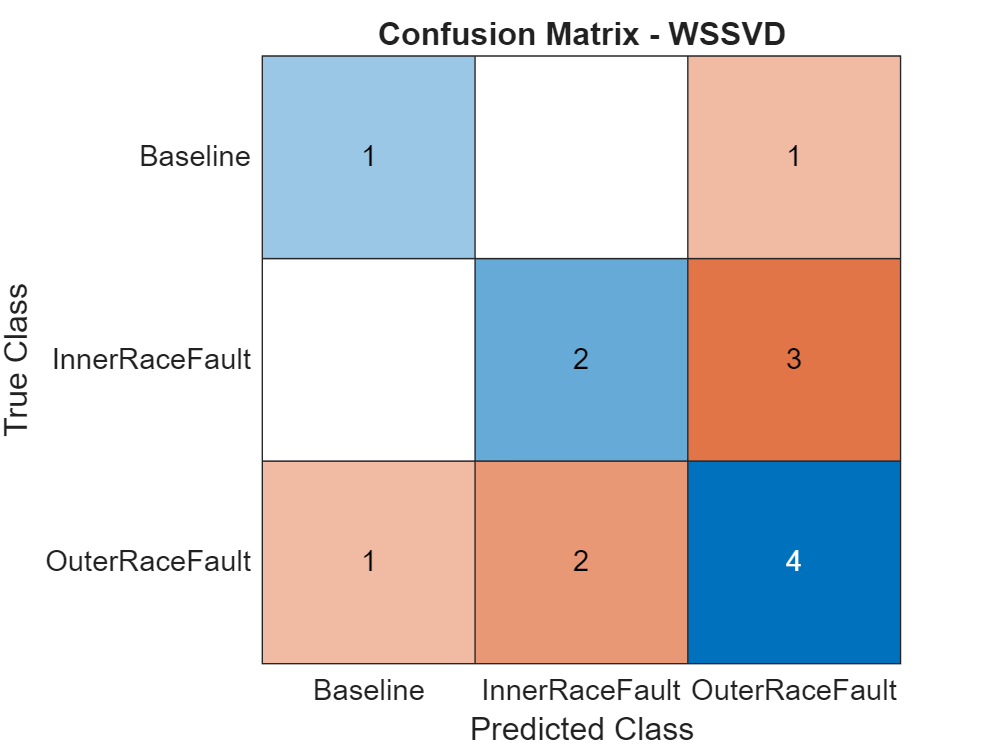


Accuracy: 0.5000


Processing dataset: WNNM


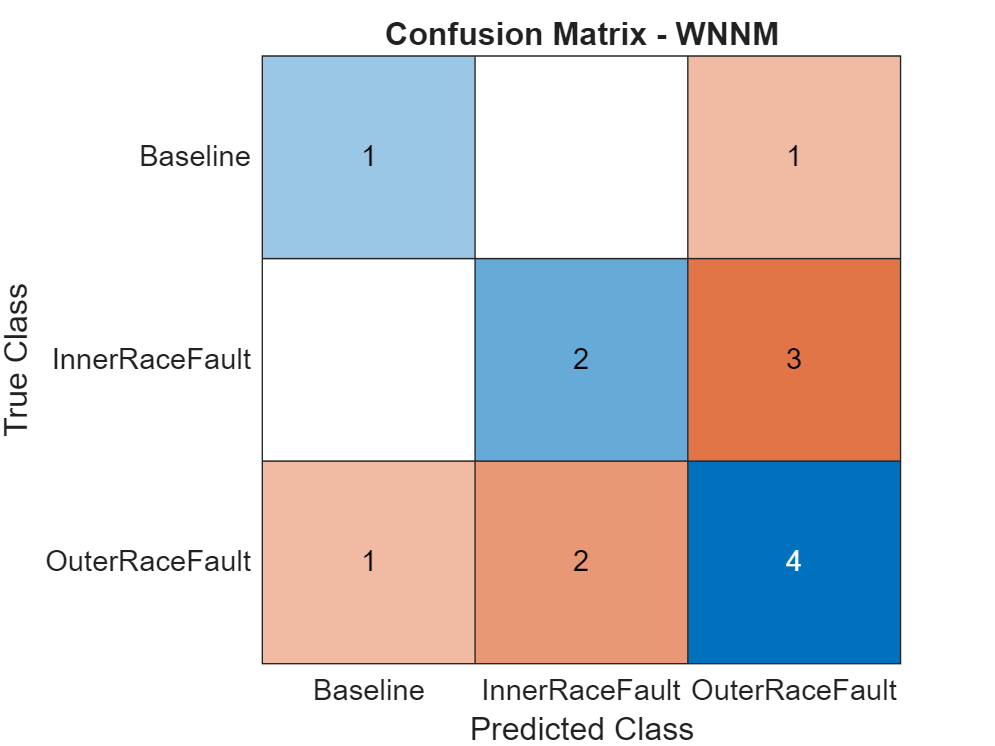


Accuracy: 0.5000


%% ============================================================
% BEARING FAULT CLASSIFICATION PIPELINE
% Random Forest + Stratified Cross Validation
% Confusion matrix uses CLASS NAMES
% ============================================================

clc
clear
close all

%% ROOT DATA DIRECTORY

root = "C:\Users\chara\OneDrive\Desktop\IMS\train_data\";

datasets = {
    root + "TSVD_signals"
    root + "RSVD_signals"
    root + "WSSVD_signals"
    root + "WNNM_signals"
};

dataset_names = {
    "TSVD"
    "RSVD"
    "WSSVD"
    "WNNM"
};

%% ============================================================

for d = 1:length(datasets)

folder = datasets{d};

fprintf('\n====================================\n')
fprintf('Processing dataset: %s\n',dataset_names{d})
fprintf('====================================\n')

files = dir(fullfile(folder,'*.mat'));

features = [];
labels = [];

%% LOAD SIGNAL FILES

for i = 1:length(files)

fileName = files(i).name;
filePath = fullfile(folder,fileName);

data = load(filePath);
vars = fieldnames(data);

signal = [];

for v = 1:length(vars)

candidate = data.(vars{v});

if isnumeric(candidate)

vec = candidate(:);

if length(vec) > 100
signal = vec;
break
end

end

end

if isempty(signal)
continue
end

%% CLASS LABELS

fname = lower(fileName);

if contains(fname,"baseline")

label = "Baseline";

elseif contains(fname,"innerracefault")

label = "InnerRaceFault";

elseif contains(fname,"outerracefault")

label = "OuterRaceFault";

else

continue

end

%% FEATURE EXTRACTION

f1 = rms(signal);
f2 = std(signal);
f3 = kurtosis(signal);
f4 = skewness(signal);
f5 = peak2peak(signal);
f6 = sum(signal.^2);

features = [features; [f1 f2 f3 f4 f5 f6]];
labels = [labels; label];

end

%% PREPARE DATA

labels = categorical(labels);
features = normalize(features);

%% STRATIFIED CROSS VALIDATION

cv = cvpartition(labels,'KFold',5);

all_pred = [];
all_true = [];

for k = 1:cv.NumTestSets

trainIdx = training(cv,k);
testIdx = test(cv,k);

X_train = features(trainIdx,:);
Y_train = labels(trainIdx);

X_test = features(testIdx,:);
Y_test = labels(testIdx);

%% RANDOM FOREST MODEL

model = TreeBagger(50,X_train,Y_train,'Method','classification');

%% PREDICT

pred = predict(model,X_test);
pred = categorical(pred);

all_pred = [all_pred; pred];
all_true = [all_true; Y_test];

end

%% CONFUSION MATRIX

figure
confusionchart(all_true,all_pred)

title("Confusion Matrix - " + dataset_names{d})

%% ACCURACY

accuracy = mean(all_true == all_pred);

fprintf("\nAccuracy: %.4f\n",accuracy)

end